# **Modelar la Incertidumbre en Sistemas Físicos**

`Autor: Dr. Abdelmalik Moujahid`

## **Variabilidad en los parámetros:**

Supongamos que queremos modelar un sistema dinámico simple descrito por una ecuación diferencial ordinaria (ODE) que incluye incertidumbre en uno de sus parámetros. 

Por ejemplo, consideremos el siguiente sistema:


$$\frac{\mathrm{dx}}{\mathrm{dt}}=-\alpha \;x$$


Donde  $x$ es la variable de estado y $\alpha \;$ es un parámetro incierto. 

Podemos modelar la incertidumbre en  $\alpha \;$ asumiendo que $\alpha \;$ sigue una **distribución normal con cierta media y desviación estándar**.

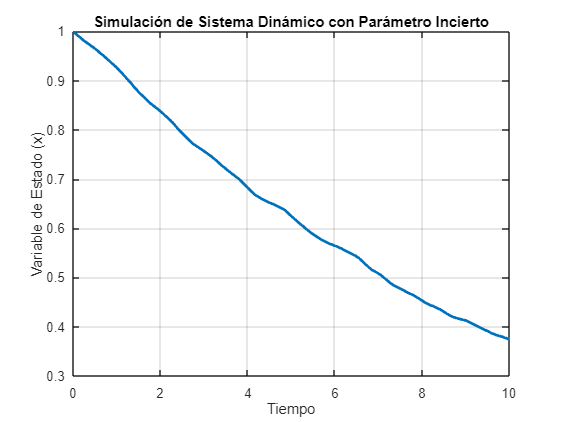


% Parámetros del sistema
Cd_media = 0.1;  % Media de alpha
Cd_desviacion = 0.02;  % Desviación estándar de alpha

% Definición de la ODE
ode = @(t, x, alpha) -alpha.* x;

% Función para simular el sistema con parámetro incierto
simular_sistema = @(t, x) ode(t, x, normrnd(Cd_media, Cd_desviacion));

% Condiciones iniciales y tiempo de simulación
x0 = 1;  % Condición inicial
tiempo_simulacion = [0 10];

% Simulación del sistema
[t, solucion] = ode45(simular_sistema, tiempo_simulacion, x0);

% Gráfico de la solución
figure;
plot(t, solucion, 'LineWidth', 2);
title('Simulación de Sistema Dinámico con Parámetro Incierto');
xlabel('Tiempo');
ylabel('Variable de Estado (x)');
grid on;

## **Ruido estocástico**

El ruido blanco es una secuencia de variables aleatorias no correlacionadas y con media cero. Cada variable aleatoria en la secuencia tiene la misma varianza, y no hay correlación entre las variables en diferentes puntos temporales. 

El ruido blanco es fundamental en la modelización de sistemas estocásticos y a menudo se utiliza para representar la componente aleatoria no predecible de un proceso.

En el contexto de un sistema dinámico descrito por una ecuación diferencial ordinaria (ODE), podríamos introducir ruido blanco para modelar la incertidumbre o la variabilidad en el sistema.

Por ejemplo, consideremos el siguiente sistema:


$$\frac{\mathrm{dx}}{\mathrm{dt}}=-\alpha \;x$$


Donde  $x$ es la variable de estado y $\alpha \;$ es un parámetro positivo que determina la tasa de decaimiento exponencial. 

Para incluir el ruido blanco en la solución, generalmente se utiliza el término de ruido estocástico, que puede ser modelado como una variable aleatoria gaussiana $\eta \;\left(t\right)$ con media cero y varianza $\sigma^2$:


$$\frac{\mathrm{dx}}{\mathrm{dt}}=-\alpha \;x+\sigma \;\eta \;\left(t\right)$$


Esta ecuación describe la evolución temporal de la variable de estado x(t) en presencia de ruido blanco. 

La constante $\sigma \;$ controla la intensidad del ruido en el sistema.

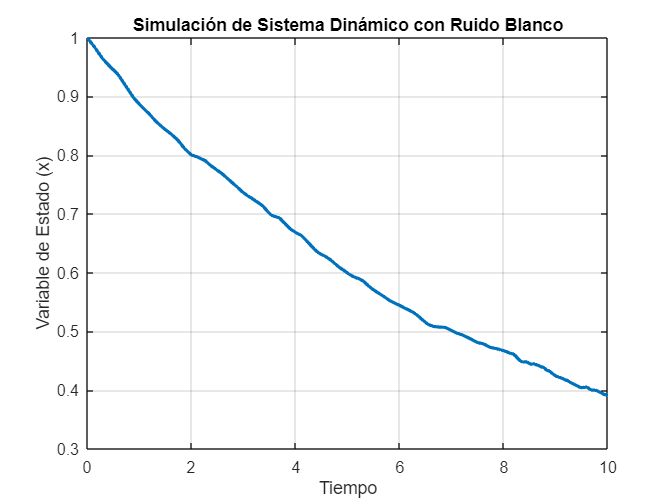

clear all
close all

% Parámetros del sistema
alpha = 0.1;  % Parámetro del sistema
sigma = 0.02;  % Desviación estándar del ruido blanco

% Definición de la ODE
ode = @(t, x) -alpha * x;

% Función para simular el sistema con ruido blanco
simular_sistema = @(t, x) ode(t, x) + sigma * randn(size(x));

% Condiciones iniciales y tiempo de simulación
x0 = 1;  % Condición inicial
tiempo_simulacion = [0 10];

% Simulación del sistema con ruido blanco
[t, solucion] = ode45(simular_sistema, tiempo_simulacion, x0);

% Gráfico de la solución
figure;
plot(t, solucion, 'LineWidth', 2);
title('Simulación de Sistema Dinámico con Ruido Blanco');
xlabel('Tiempo');
ylabel('Variable de Estado (x)');
grid on;

## Modelo de bala de cañon

**Variabilidad en los parámetros**

clear all
close all

% Parámetros del sistema
rho = 0.074;
A = 0.4;
v0 = 50;
theta0 = pi/6;
g = 9.81;           % Aceleración debida a la gravedad (m/s^2)


Cd_media = 0.4;  % Media de alpha
Cd_desviacion = 0.2;  % Desviación estándar de alpha

% Definición de la ODE
ode = @(t, x, Cd) [x(2);-sign(x(2))*.5*rho*A*x(2).^2*Cd;x(4);-g-sign(x(4))*.5*rho*A*x(4).^2*Cd];

% Set the options for the ODE solver, including the event function
options = odeset('Events', @zeroCrossingEvent);

% Función para simular el sistema con parámetro incierto
simular_sistema = @(t, x) ode(t, x, normrnd(Cd_media, Cd_desviacion));

% Condiciones iniciales y tiempo de simulación
x0 = [0 v0*cos(theta0) 20 v0*sin(theta0)];  % Condición inicial
tiempo_simulacion = [0 6];

% Simulación del sistema
[t, solucion] = ode45(simular_sistema, tiempo_simulacion, x0,options);


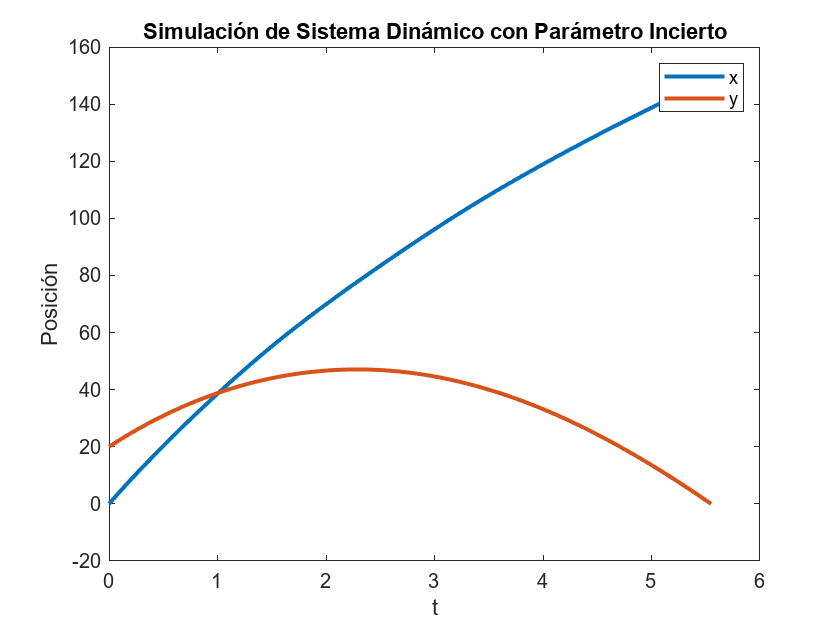

% Gráfico de la solución
figure;
plot(t, [solucion(:,1),solucion(:,3)], 'LineWidth', 2);
title('Simulación de Sistema Dinámico con Parámetro Incierto');
xlabel('t');
ylabel('Posición');
legend('x','y')

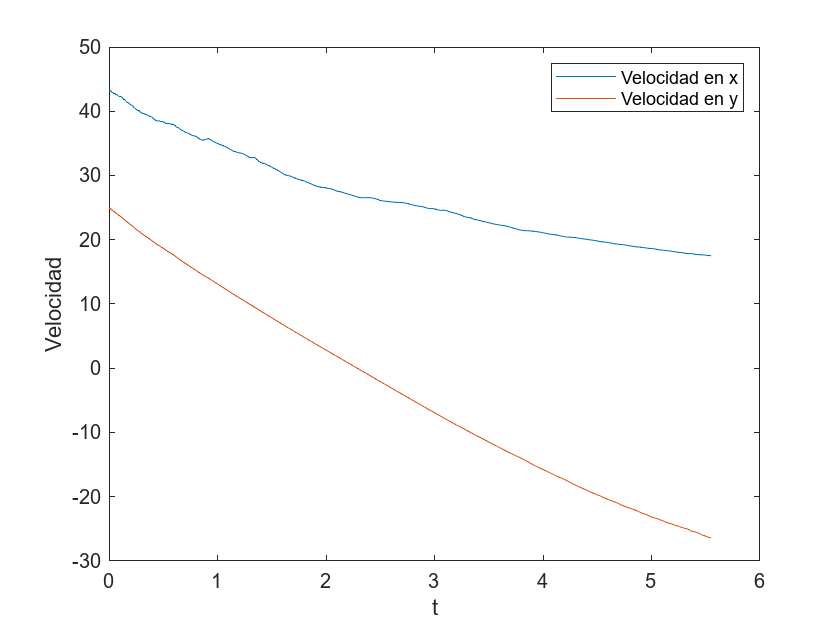

figure;
plot(t,[solucion(:,2),solucion(:,4)]);xlabel('t');ylabel('Velocidad')
legend('Velocidad en x','Velocidad en y')

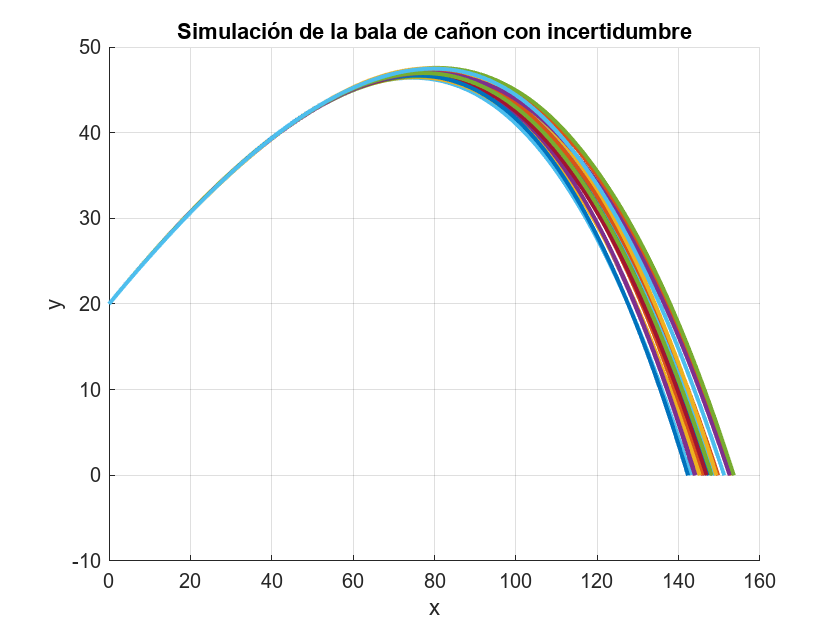


% Set the options for the ODE solver, including the event function
options = odeset('Events', @zeroCrossingEvent);


figure;
grid on
numruns = 20; % el número de experimentos
x_impacto = zeros(1,numruns);

for i=1:numruns
    % Simulación del sistema
    [t, solucion] = ode45(simular_sistema, tiempo_simulacion, x0, options);   
    x_impacto(i)=solucion(end,1);

    hold on
    plot(solucion(:,1), solucion(:,3), 'LineWidth', 2);
    title('Simulación de la bala de cañon con incertidumbre');
    xlabel('x');
    ylabel('y');

end

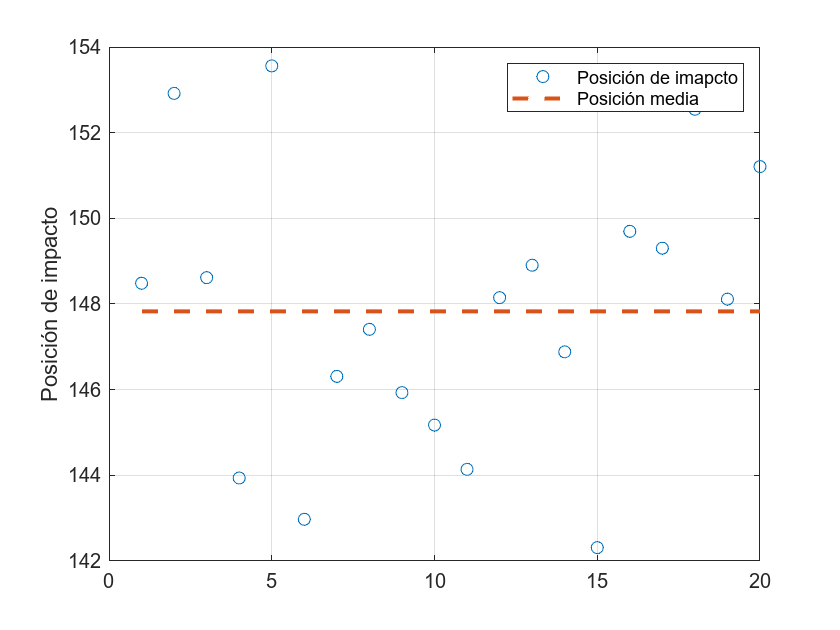

figure;
plot(x_impacto,'o');grid on;
hold on;plot(mean(x_impacto)*ones(1,numel(x_impacto)),'--','LineWidth',2)
ylabel('Posición de impacto')
legend('Posición de imapcto','Posición media')

## Pendulo Simple con Fricción

Dinámica de un péndulo simple con fricción y una fuerza sinusoidal.

La función de evento `eventoCruceCero` detecta cuando el ángulo del péndulo cruza cero y termina la simulación en ese momento. 

Vamos a introducir una** perturbación aleatoria en la fuerza sinusoidal**. 

Utilizaremos una componente de **ruido blanco con media cero y cierta desviación estándar.** 

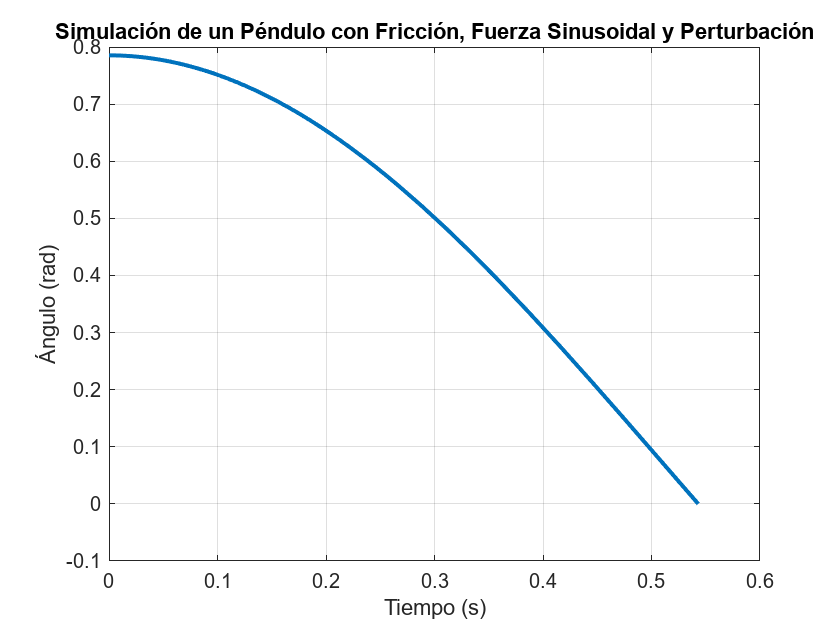

% Parámetros del péndulo
g = 9.81;      % Aceleración debida a la gravedad (m/s^2)
l = 1;         % Longitud del péndulo (m)
b = 0.2;       % Coeficiente de fricción (N*s/m)
A = 0.5;       % Amplitud de la fuerza sinusoidal (N)

omega = 2;     % Frecuencia angular de la fuerza sinusoidal (rad/s)
desviacion_perturbacion = 0.1;  % Desviación estándar de la perturbación

% Definir la ODE del péndulo con fricción, fuerza sinusoidal y perturbación
ode = @(t, theta) [theta(2); -b*theta(2) - (g/l)*sin(theta(1)) + A*sin(omega*t) + desviacion_perturbacion*randn];

% Condiciones iniciales
theta0 = [pi/4; 0];  % Ángulo inicial y velocidad angular inicial

% Configurar las opciones del solucionador de ODE con la función de evento
options = odeset('Events', @eventoCruceCero);

% Intervalo de tiempo de simulación
tspan = [0, 10];

% Llamar al solucionador de ODE con la función de evento
[t, sol] = ode45(ode, tspan, theta0, options);

% Graficar la solución
figure;
plot(t, sol(:, 1), 'LineWidth', 2);
title('Simulación de un Péndulo con Fricción, Fuerza Sinusoidal y Perturbación');
xlabel('Tiempo (s)');
ylabel('Ángulo (rad)');
grid on;


% Función de evento para detectar cruces por cero del ángulo

**La función de evento **`eventoCruceCero`** detecta cuando el ángulo del péndulo cruza cero y termina la simulación en ese momento**

function [value, isterminal, direction] = eventoCruceCero(t, theta)
    % Valor a ser evaluado (detecta cuando el ángulo cruza cero)
    value = theta(1);
    
    % Terminar la simulación cuando cruza cero
    isterminal = 1;
    
    % Detectar cruces de cero en ambas direcciones (aumento y disminución)
    direction = 0;
end


`Función de evento para detectar cuando la nave impacta con el suelo, es decir, cuando la variable y cruza cero.`

function [value, isterminal, direction] = zeroCrossingEvent(t, x)
    % Set the value to be the variable x
    value = x(3);
    
    % Terminate the simulation when x crosses zero
    isterminal = 1;
    
    % Detect both increasing and decreasing zero crossings
    direction = 0;
end
